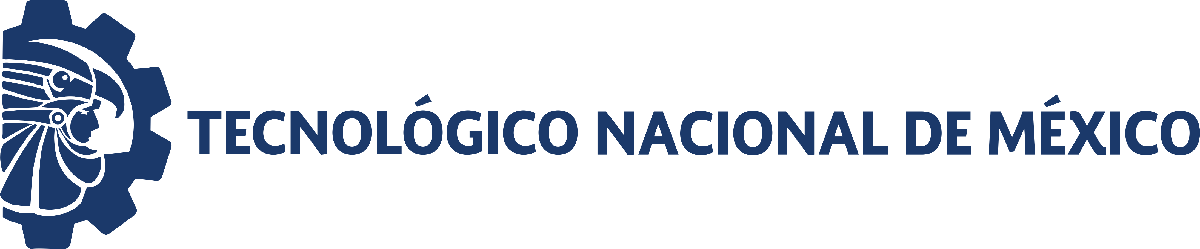                                 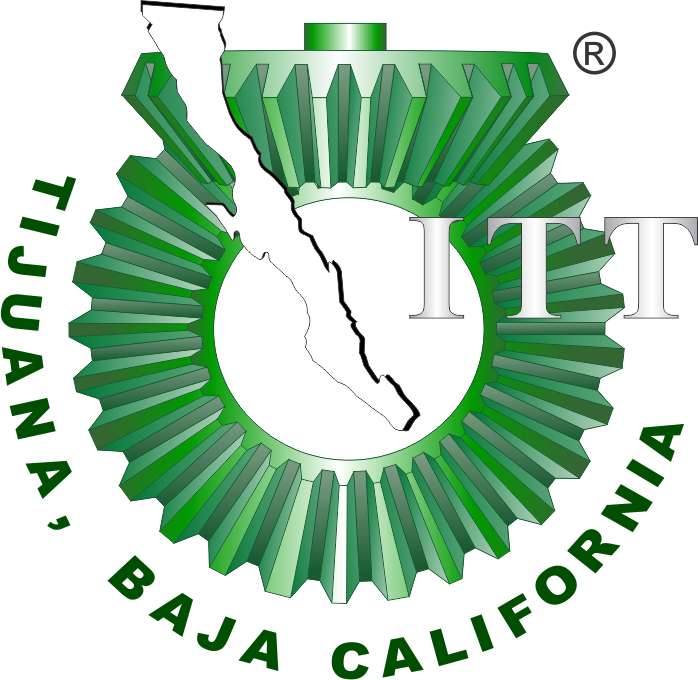

# Práctica cuatro: Sistema cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

[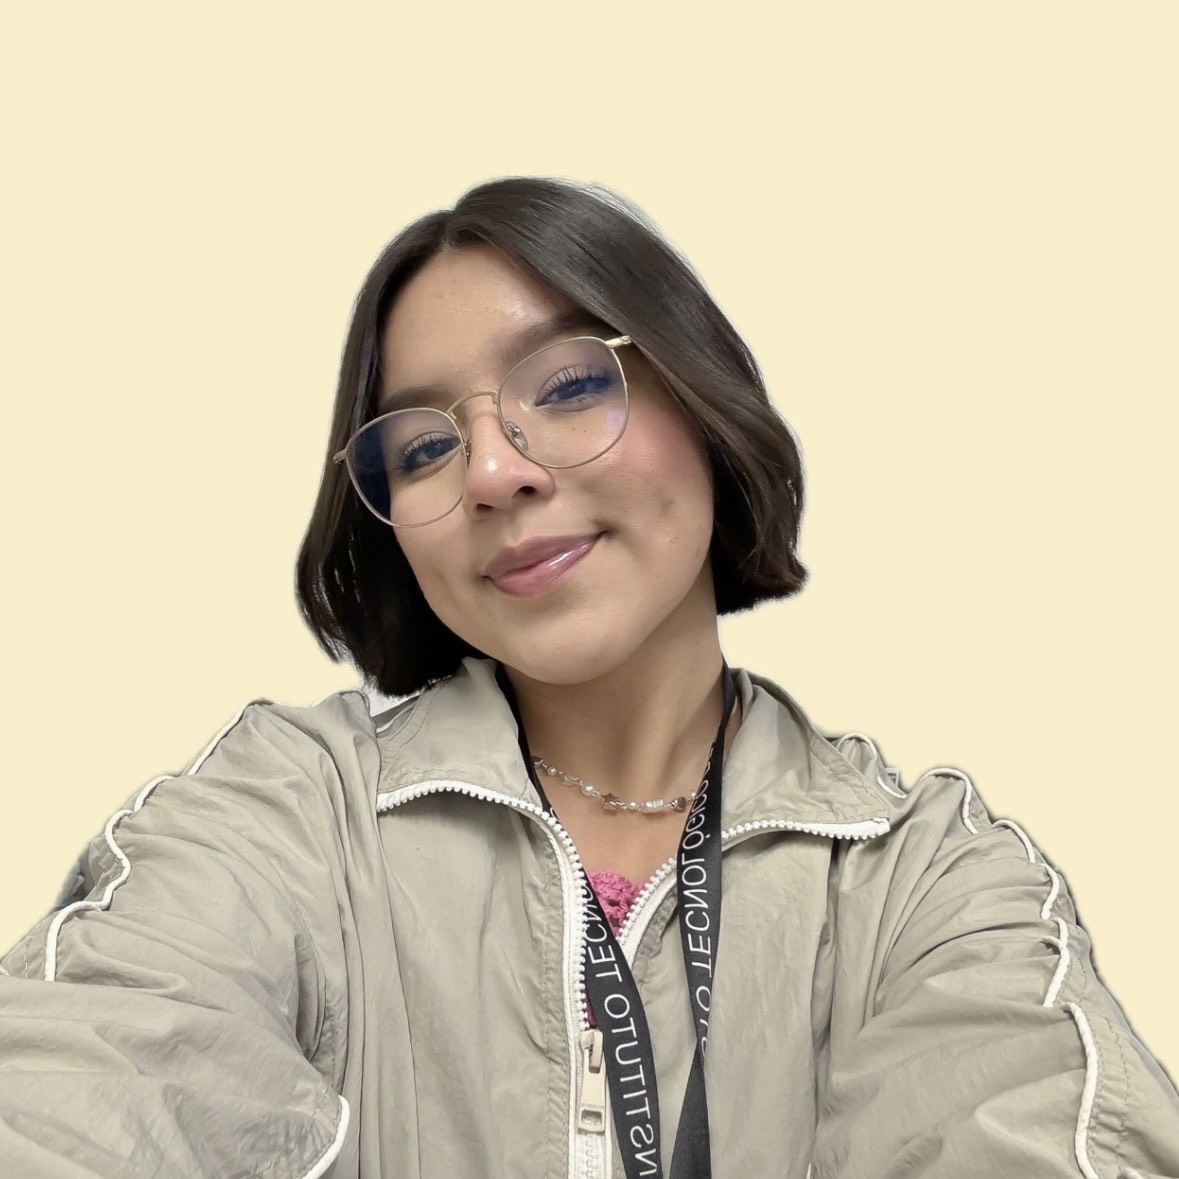]

Nombre del alumno: **Leslie Avelladith Marin Paredes **

Número de control: **20212506**

Correo institucional: **l20212506@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10'; 
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';

## Lazo Abierto

Signal = "Lazo Abierto";
file = 'Lazo_Abierto'

file = 'Lazo_Abierto'

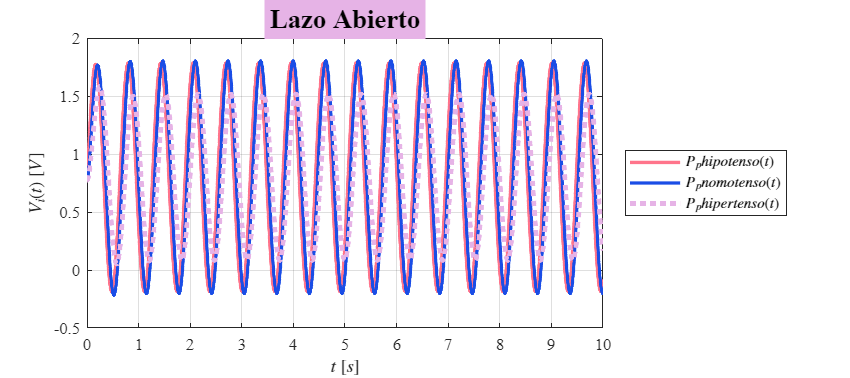

open_system(file);
x = sim(file, parameters);
plotsignals (x.t, x.Ppx, x.Ppy, x.Ppz, Signal) %to workspace buscar en el library browser del sysp0 
title('Lazo Abierto','FontSize',16,'BackgroundColor',[0.9,0.7,0.9])

## Paciente Hipotenso

## **Rendimiento del controlador para paciente Hipotenso**

kP = 0

kI = 103.328094270981

kD = 0

Signal = "Paciente Hipotenso";
file = 'LC_Hipotenso'

file = 'LC_Hipotenso'

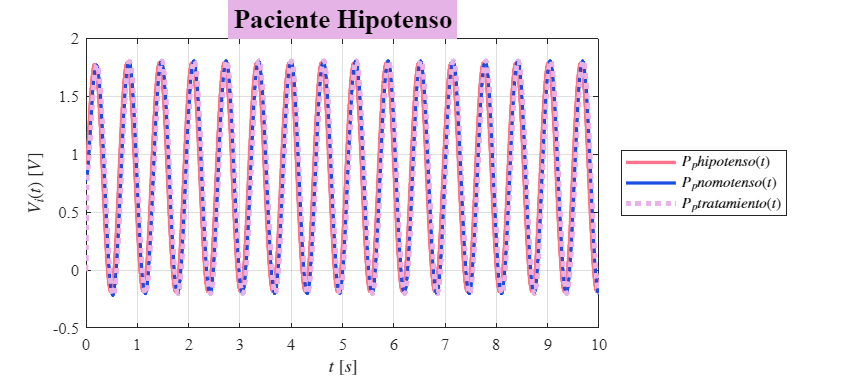

open_system(file);
x = sim(file,parameters);
plotsignals(x.t, x.Ppx, x.Ppy, x.Ppz, Signal) %to workspace buscar en el library browser del sysp0 
title('Paciente Hipotenso','FontSize',16,'BackgroundColor',[0.9,0.7,0.9])

## Paciente Hipertenso

## Rendimiento del controlador Hipertenso

kP = 0.00016767

kI = 551.4981

kD = 0

Signal = "Paciente Hipertenso";
file = 'LC_Hipertenso'

file = 'LC_Hipertenso'

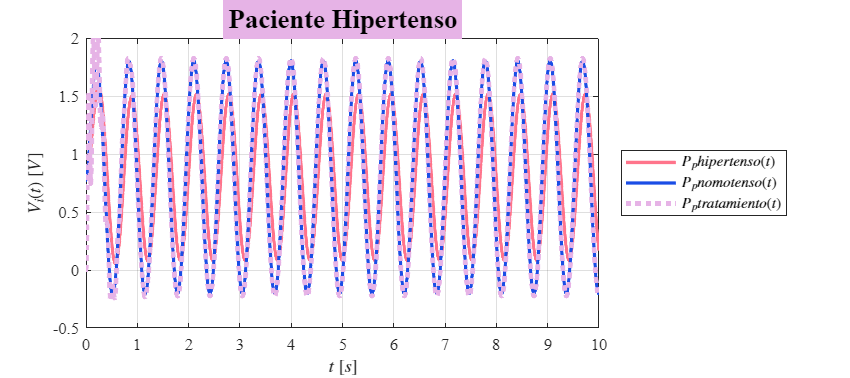

open_system(file);
x = sim(file,parameters);
plotsignals(x.t,x.Ppx,x.Ppy,x.Ppz,Signal) %to workspace buscar en el library browser del sysp0 
title('Paciente Hipertenso','FontSize',16,'BackgroundColor',[0.9,0.7,0.9])

## **Función: Respuesta del sistema con y sin tratamiento**

function plotsignals(t,Ppx,Ppy, Ppz, Signal)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[1,1,18,8])
    set(gca,'FontName','Times New Roman')
    fontsize(10, 'points')

    am = [255/255, 116/255, 139/255];
    rf = [0.1,0.3,0.9];
    na = [0.9,0.7,0.9];

    hold on; grid on; box on;

    plot(t, Ppx.Data,'LineWidth',2,'Color',am)
    plot(t, Ppy.Data,'LineWidth',2,'Color',rf)
    plot(t, Ppz.Data,':','LineWidth',3,'Color',na)

    xlabel('$t$ $[s]$','Interpreter','Latex')
    ylabel('$V_{i}(t)$ $[V]$','Interpreter','Latex')

    L = legend('$P_{A}(t): Control$','$P_{A}(t): Caso$','$V_{A}(t): Tratamiento$');
    set(L,'Interpreter','Latex','Location','Bestoutside','Box','On')

    if Signal == "Lazo Abierto"
        L = legend('$P_{p}{hipotenso}(t)$',  '$P_{p}{nomotenso}(t)$', '$P_{p}{hipertenso}(t)$');
         set(L,"Interpreter","Latex","Location",'eastoutside',"Box","On")
         exportgraphics(gcf, ['Lazo Abierto', '.pdf'], 'ContentType', 'vector');

    elseif Signal == "Paciente Hipotenso"
        L = legend('$P_{p}{hipotenso}(t)$',  '$P_{p}{nomotenso}(t)$', '$P_{p}{tratamiento}(t)$');
        set(L,"Interpreter","Latex","Location",'eastoutside',"Box","On")
        exportgraphics(gcf, ['Paciente Hipotenso', '.pdf'], 'ContentType', 'vector');
    elseif Signal == "Paciente Hipertenso"
        L = legend('$P_{p}{hipertenso}(t)$',  '$P_{p}{nomotenso}(t)$', '$P_{p}{tratamiento}(t)$');
        set(L,"Interpreter","Latex","Location",'eastoutside',"Box","On")
        xlim([0,10]); xticks(0:1:10)  %dominio
        ylim([-0.5,2.00]); yticks(-0.5:0.5:2)  %rango
        exportgraphics(gcf, ['Paciente Hipertenso', '.pdf'], 'ContentType', 'vector');
    end
   % exportgraphics(gcf, [Signal, '.pdf'], 'ContentType', 'vector')
end